# Hubble Law Part 3: Extracting the Hubble Constant $H_{o}$

In part 1 of the lab we calculated the radial velocities of galaxies receding from our line of sight using the redshift of the hydrogen alpha line. Whereas in part 2 we filled in the games of the missing distances to these galaxies by measuring its angular size and taking advantage of the average size of a spiral galaxy. The Hubble Law can now be investigated using the galactic information acquired. In the end of this notebook you'll be in a position to quote a final measured Hubble constant from applying regression models onto the data, as well as, goodness-of-fit statistics and comparisons. These final results will include:

- Hubble Constant: $H_{o} \pm \sigma_{H}$.

- Residuals of the regression.

- Goodness-of-fit: $\chi^2$, degrees of freedom, p-value.

- Comparison: Student T-test using literature values.

## Read in$(V_{radial}$$,D_{galactic})$:

Read in te distances from the file *distances.txt *and velocities from *radial_vel.txt *into arrays. Both files should be ordered in the same manner (in increasing NGC galaxy designation).

directory = '~/tutorialSims/HubbleLaw/NGCData/';

dis_data = dlmread(strcat(directory,"distances.txt"));
vel_data = dlmread(strcat(directory,"radial_vel.txt"));

distances = dis_data(:,2);
velocities = vel_data(:,1);
velocities_std = vel_data(:,2);

Visualize the data with error bars to inspect for any possible correlation.

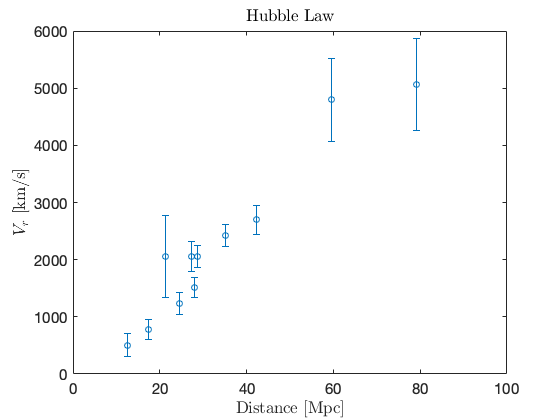

p0 = errorbar(distances, velocities, velocities_std,'o');
xlim([0,100])
set(gca,'fontsize',15)
title('Hubble Law','Interpreter','latex')
xlabel('Distance [Mpc]','Interpreter','latex')
ylabel('$V_{r}$ [km/s]','Interpreter','latex')
hold on;

## Linear Regression:

Hubble's Law is a linear relation, meaning, we can take advantage of MATLAB's $\chi^2 $-fitting and linear regression methods. Similar to how we fit a Gaussian to the spectral lines, we'll additionally feed it the algorithm an additional parameter, the 'weight'. The weight is defined as $w = 1/\sigma^2$. We'll be using the two parameter linear function *poly1 *as our fit model. Which is defined as, 


$$v(d| p_1,p_2) = p_{1} \cdot d + p_{2}$$


Where $v$ is the radial velocity in km/s, $d$ is the galactic distance in Mpc, and the $p_1$ is the estimated Hubble Constant $H_{o}$.

[f, gof, fit_output] = fit(distances,velocities,'poly1','Weights', ...
                                                 velocities_std.^(-2));
f

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       79.77  (62.46, 97.08)
       p2 =      -514.7  (-1007, -22.35)

Similar to part 1, created a linear function from the parameter's estimated from the regression. Create an array of linearly spaced distance values which is used to construct the final function. Plot this on top of our data. How does it look visually?

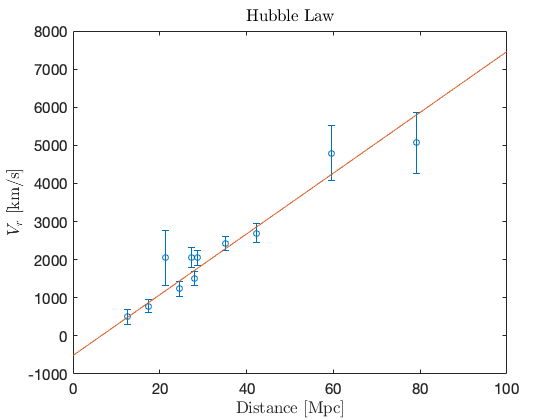

x_dis = linspace(0,100,100);
line = f.p1*x_dis + f.p2;
plot(x_dis,line)

## Error Analysis, Goodness-of-fit, and P-value:

To extract the estimated errors on the parameters, use the Jocobian matrix to calculate covariance matrix. Keeping in mind that the diagonals on the covariance matrix equal the variance on the parameters $Var[p_{i}]$, in order $i = (1,2)$. 

J = fit_output.Jacobian;           %extract the jocobian matrix
covariance_matrix = inv(J'*J)

covariance_matrix = 	1.0e+04 *

    0.0049   -0.1303
   -0.1303    3.9561


#### Quote the estimated Hubble Constant $H_{o}$:

hubble_const = f.p1

hubble_const = 79.7690

#### Quote the estimated error $\sigma_{H}$:

hubble_const_std = sqrt(covariance_matrix(1,1))

hubble_const_std = 6.9929

Having the final estimated value and associated error $H_{o} \pm \sigma_{H}$ isn't enough. To feel confident in these results we need test the goodness of the fit. Specifically, the minimum $\chi^2$, the number of degrees of freedom, and the p-value of the observation. Keeping in mind that a proper statistical inference needs all three of these pieces. A p-value alone doesn't convey enough information to make a proper statistical statement of the data. 

#### Quote the minimum $\chi^2$ value:

min_chi_2 = gof.sse

min_chi_2 = 10.7749

#### Quote the number of degrees of freedom = $N_{data} - N_{parameters}$:

ndof = gof.dfe;

#### Last but not least, the p-value of getting $H_{o}$ given the model, $p = \int^{\infty}_{\chi^2_{\text{min}}} f(x|\nu) dx$:

p_value = chi2cdf(min_chi_2, ndof, 'upper')

p_value = 0.2915

reduced_chi2 = min_chi_2/ndof

reduced_chi2 = 1.1972

## Student's T-test Comparison:

The Hubble's consant was estimated from a linear regression with levels of success and significance. Even if our test-statistics increased our confidence in our model we still need to compare our estimated value with that of other literature values. As mentioned in the introduction, there are many independent techniques of measuring the Hubble Constant. We'll compare our value with that of the PLANK Collaborations measurement using the Cosmic Microwave Background: $H_{0} = 67.4 \pm 0.5 \text{ km s}^{-1} \text{ Mpc}^{-1}$ (https://doi.org/10.1051/0004-6361/201833910). The Student t-test statistic is a standard method of comparing two means (our measurment and literature value) and testing whether they are sampled from the same distribution. The null hypothesis is that our two values are sampled from the same physical process, or distribution using,


$$t = \frac{|H^{\text{fit}} - H^{CMB}|}{\sqrt{\sigma_{H,\text{fit}}^2 + \sigma_{H,CMB}^2 }
$$


Where $t < 2$ is consistent with our null hypothesis (they are consistent within 95% CL), and $t >2 $ is inconsistent with our null hypothesis. 

hubble_const_cmb = 67.4;
hubble_const_cmb_std = 0.5;

t = abs((hubble_const_cmb) -(hubble_const))/sqrt((hubble_const_cmb_std)^2 ...
                                                       + (hubble_const_std)^2)

t = 1.7643

## Questions: